clear clc
syms Rin Rf ri ro positive

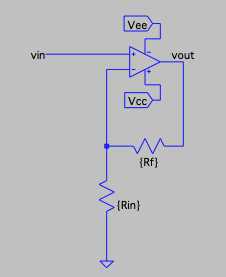

# Impedancia de entrada do ampop

Percorrendo vin encontra-se primeiro ri que que está em serie com uma associação de resistores, assim:

ZinAmp = ri

$$ZinAmp = \mathrm{ri}$$

Em seguida soma-se o resultado anterior com o paralelo entre Rin e Rf + ro. Dessa forma:

ZinAmp = ZinAmp + paraleloSym(Rin, (Rf + ro))

$$ZinAmp = \mathrm{ri}+\frac{1}{\frac{1}{\mathrm{Rf}+\mathrm{ro}}+\frac{1}{\mathrm{Rin}}}$$

# Impedancia de saida do ampop

Percorrendo vout encontra-se ro que está em paralelo com uma associação de resistores, assim:

ZoutAmp = ro

$$ZoutAmp = \mathrm{ro}$$

Em seguida é possível perceber que essa associação é composta por Rf + Rin//ri. Dessa forma:

ZoutAmp = paraleloSym(ZoutAmp, Rf + paraleloSym(ri, Rin))

$$ZoutAmp = \frac{1}{\frac{1}{\mathrm{Rf}+\frac{1}{\frac{1}{\mathrm{Rin}}+\frac{1}{\mathrm{ri}}}}+\frac{1}{\mathrm{ro}}}$$